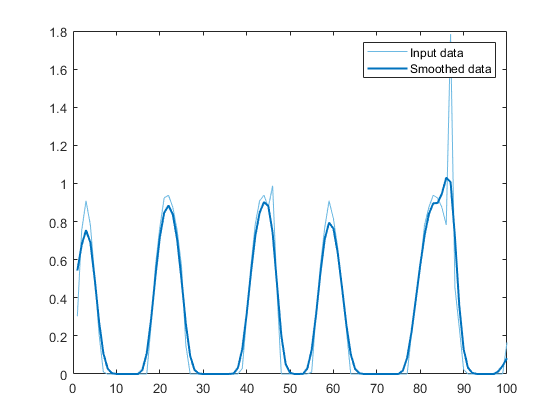

% Smooth input data
smoothedData = smoothdata(senal2,'gaussian','SmoothingFactor',0.25);

% Display results
clf
plot(senal2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

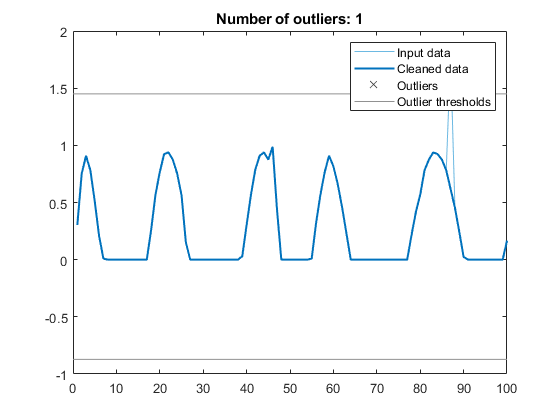

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(senal2,'mean');

% Display results
clf
plot(senal2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierIndices),cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),senal2(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh] = isoutlier(senal2,'mean');

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear thresholdLow thresholdHigh

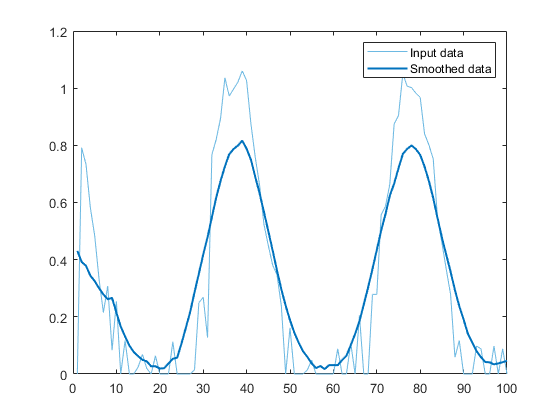

% Smooth input data
smoothedData2 = smoothdata(senal1,'movmean','SmoothingFactor',0.25);

% Display results
clf
plot(senal1,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

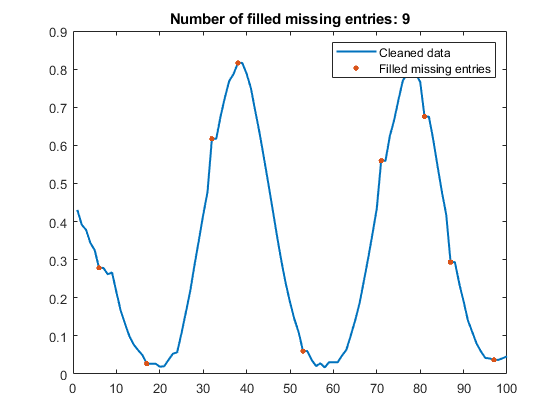

% Fill missing data
[cleanedData2,missingIndices2] = fillmissing(senal1_s_nans,'next');

% Display results
clf
plot(cleanedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(find(missingIndices2),cleanedData2(missingIndices2),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices2))])

hold off
legend

clear missingIndices2